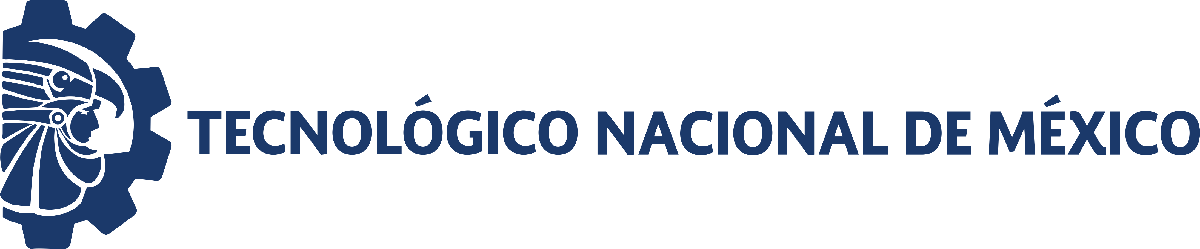                                 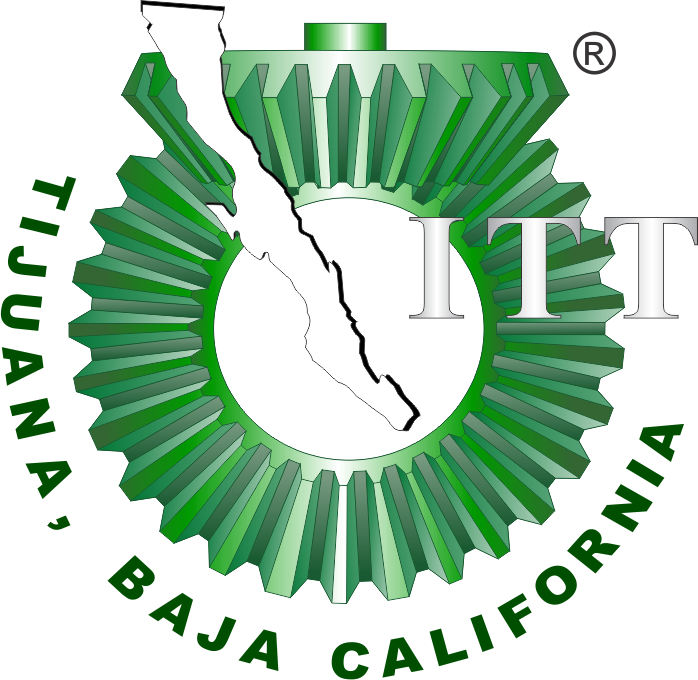

# Práctica 3: Sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general                                                                                                            

                                                                                                         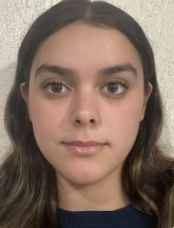

Nombre del alumno: Anette Mariana Vidal Ortiz

Número de control: 22212389

Correo institucional: L22212389**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistema';
open_system(file);
parameters.StopTime=tend;
parameters.Solver = 'ode23t';
parameters.MaxStep='1E-3';
x = sim(file,parameters);

## Lazo Abierto

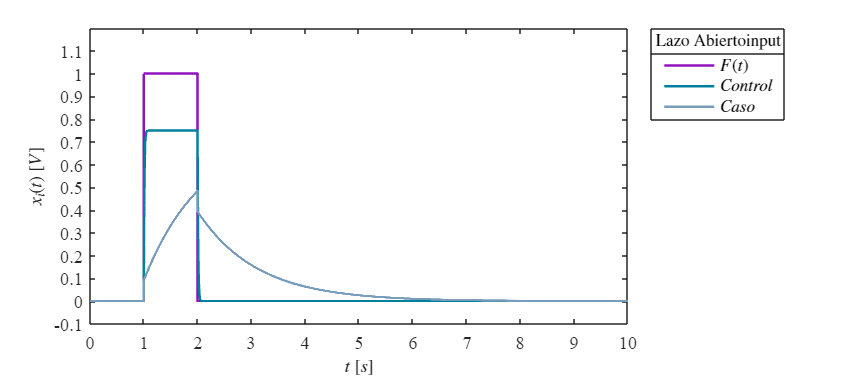

plotsignals(x.t,x.F,x.Fs1,x.Fs2)

## Lazo Cerrado

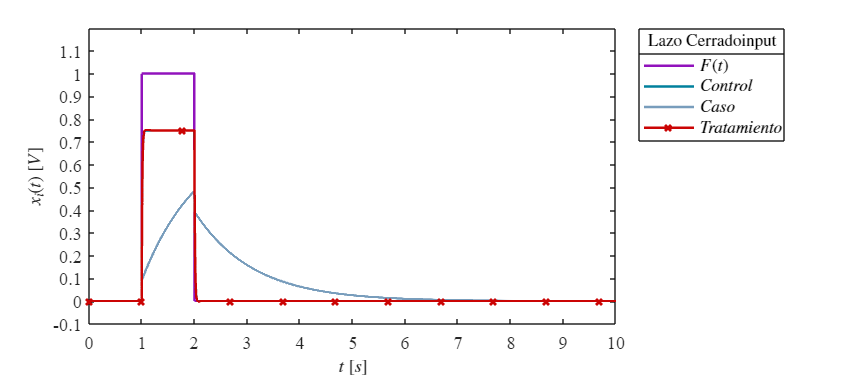

plotsignals1(x.t,x.F,x.Fs1,x.Fs2,x.Fs3)

## Funcion : Respuesta a las señales

function plotsignals(t,F,Fs1,Fs2,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [145,18,188;
                0,128,157;
                120,157,188;
                203,4,4;
                125,150,117;
                0,0,1]/255;
    colororder(mycolors)

    p = plot(t,F,'-',t,Fs1,'-',t,Fs2,'-',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    L = legend('$F(t)$','$Control$','$Caso$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,['Lazo Abierto','input'],'FontSize',10)


    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

     xlim([0,10]); xticks(0:1:10);
     ylim([-0.1 1.2]); yticks(-0.1:0.1:1.1);
exportgraphics(gcf,'Lazo Abierto.pdf','ContentType','vector')
exportgraphics(gcf,'Lazo Abierto.png','ContentType','vector')
end

function plotsignals1(t,F,Fs1,Fs2,Fs3)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [145,18,188;
                0,128,157;
                120,157,188;
                203,4,4;
                125,150,117;
                0,0,1]/255;
    colororder(mycolors)

    p = plot(t,F,'-',t,Fs1,'-',t,Fs2,'-',t,Fs3,'-x',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    L = legend('$F(t)$','$Control$','$Caso$','$Tratamiento$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,['Lazo Cerrado','input'],'FontSize',10)


    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

     xlim([0,10]); xticks(0:1:10);
     ylim([-0.1 1.2]); yticks(-0.1:0.1:1.1);
exportgraphics(gcf,'Lazo cerrado.pdf','ContentType','vector')
exportgraphics(gcf,'Lazo cerrado.png','ContentType','vector')
end